# `DEMO_05:`    4-bar linkage analysis** - velocity analysis**

Let's look at a simple example where we want to compute the velocities of certain points and links of a 4bar mechanism.  Some good examples of this type of analysis can be found in Rreferences 1 and 2 below.  After reviewing this example, have a look at the following slightly more complicated example:

-  `DEMO_06_bh_4bar_matrix_velocity_analysis.mlx` which considers a machine in a more "general pose".

**REFs:**

- [https://www.youtube.com/watch?v=rikzb5xf0Mo](https://www.youtube.com/watch?v=rikzb5xf0Mo)  (Rick Hill, University of Detroit Mercy)

- [https://www.youtube.com/watch?v=gQKGKuqH8w4](https://www.youtube.com/watch?v=gQKGKuqH8w4)   (CPPMechEngTutorials)

`Bradley Horton : 24-Jul-2019, bhorton@mathworks.com`

# Our **specific** problem:

For the instant shown below, compute the following:

- The velocity of point P

- The angular velocity $\omega_{\textrm{CA}}$

**Figure 01:  the 4bar linkage**

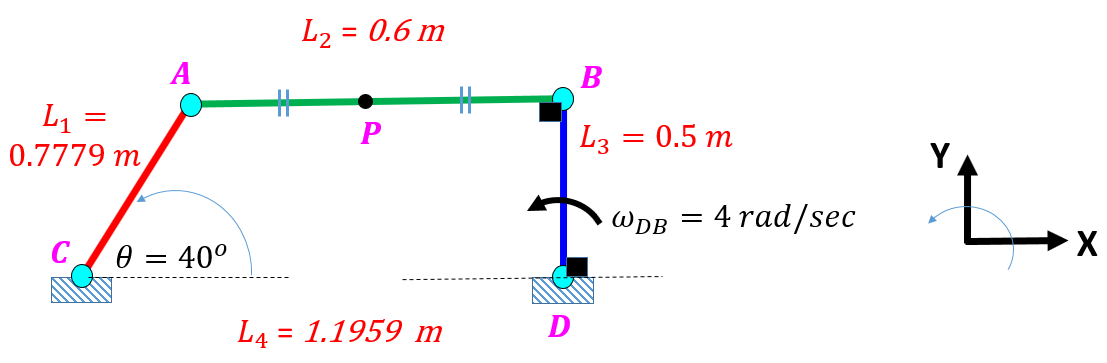

Start with a clean slate and remove any previous assumptions from the Symbolic engine

clear all 

Define our machine's parameters:

syms    theta  L_1  L_2  L_3    real
syms omega_DB                   real 
syms omega_CA                   real
syms omega_AB                   real

**Define the known angular velcity vector of link DB : **

*NOTE:  we of course know that  *$\omega_{\textrm{DB}} =4\;\frac{\textrm{rad}}{\sec }$*,  but let's hold off inserting numeric values until the end.*

omega_DB_vec = [0;0;omega_DB]

$$omega\_DB\_vec = \left(\begin{array}{c} 0\\ 0\\ \omega_{\mathrm{DB}} \end{array}\right)$$

**Compute  **$v_B$** :**

- $v_B =\omega_{\mathrm{DB}} \times r_{B\left|D\right.}$  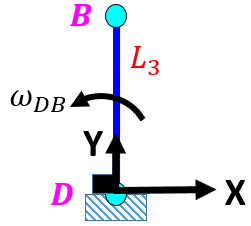

*NOTE:  we of course know that  *$\omega_{\textrm{DB}} =4\;\frac{\textrm{rad}}{\sec }$*, and *$L_3 =0\ldotp 5\;m$,* but let's hold off inserting numeric values until the end.*

R_B_relto_D_vec = [0;L_3;0];
v_B_vec         = cross( omega_DB_vec, R_B_relto_D_vec )

$$v\_B\_vec = \left(\begin{array}{c} -L_{3}\,\omega_{\mathrm{DB}}\\ 0\\ 0 \end{array}\right)$$

**Define  **$v_A$ 

- $v_A =\omega_{\mathrm{CA}} \times r_{A\left|C\right.}$  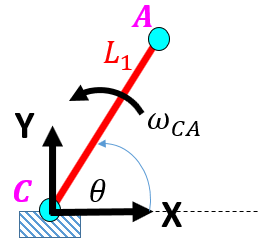

*NOTE:  we of course know that  *$\theta ={40}^{\circ } =\frac{\pi \ldotp 40}{180}\;\textrm{rads}$*, but let's hold off inserting numeric values until the end.*

R_A_relto_C_vec = [ L_1*cos(theta);
                    L_1*sin(theta);
                    0 ];
                
omega_CA_vec    = [0;0;omega_CA];         
             
v_A_vec         = cross( omega_CA_vec, R_A_relto_C_vec )

$$v\_A\_vec = \left(\begin{array}{c} -L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\theta \right)\\ L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

**Define  **$v_P$** using **$v_B$

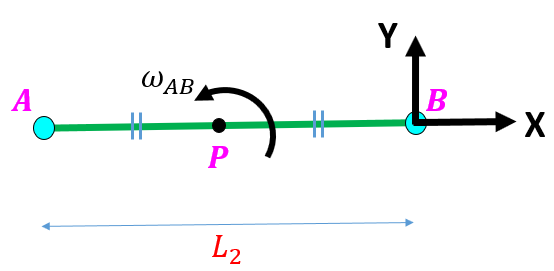

- 
$$v_P =v_B \;\;\;\;+\;\;v_{P\left|B\right.}$$


- 
$$v_P =v_B \;\;\;\;+\;\;\;\;\omega_{\mathrm{AB}} \times r_{P\left|B\right.}$$
   

R_P_relto_B_vec = [-L_2/2;0;0];
omega_AB_vec    = [0;0;omega_AB];
v_P_using_B_vec = v_B_vec  +  cross(omega_AB_vec, R_P_relto_B_vec)

$$v\_P\_using\_B\_vec = \left(\begin{array}{c} -L_{3}\,\omega_{\mathrm{DB}}\\ -\frac{L_{2}\,\omega_{\mathrm{AB}}}{2}\\ 0 \end{array}\right)$$

**Define  **$v_P$** using **$v_A$

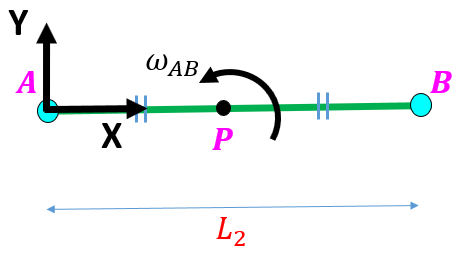

- 
$$v_P =v_A \;\;\;\;+\;\;v_{P\left|A\right.}$$


- 
$$v_P =v_A \;\;\;\;+\;\;\;\;\omega_{\mathrm{AB}} \times r_{P\left|A\right.}$$


R_P_relto_A_vec = [L_2/2;0;0];
v_P_using_A_vec = v_A_vec  +  cross(omega_AB_vec, R_P_relto_A_vec)

$$v\_P\_using\_A\_vec = \left(\begin{array}{c} -L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\theta \right)\\ \frac{L_{2}\,\omega_{\mathrm{AB}}}{2}+L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

So we now have 2 expressions for $v_P$ and they  must of course be equal.   

EQ_P = v_P_using_B_vec == v_P_using_A_vec

$$EQ\_P = \left(\begin{array}{c} -L_{3}\,\omega_{\mathrm{DB}}=-L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\theta \right)\\ -\frac{L_{2}\,\omega_{\mathrm{AB}}}{2}=\frac{L_{2}\,\omega_{\mathrm{AB}}}{2}+L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\theta \right)\\ 0=0 \end{array}\right)$$

Remember that we have been given numeric values for:

- 
$$L_1 ,L_2 ,L_3 ,\theta ,\omega_{\textrm{DB}} \;$$
 

So the 2 unknowns that we need to solve for are $\omega_{\textrm{AB}}$ and $\omega_{\textrm{CA}}$.  

By inspecting EQ_P above, you can see that we have the familiar pattern of 2 equations with 2 unknowns ... which we know how to solve:

THE_SOL = solve(EQ_P, [omega_AB, omega_CA])

THE_SOL = struct with fields:
    omega_AB: [1×1 sym]
    omega_CA: [1×1 sym]


So $\omega_{\textrm{AB}}$ and $\omega_{\textrm{CA}}$ are:

[THE_SOL.omega_AB,  THE_SOL.omega_CA].'

$$ans = \left(\begin{array}{c} -\frac{L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\theta \right)}{L_{2}\,\sin\left(\theta \right)}\\ \frac{L_{3}\,\omega_{\mathrm{DB}}}{L_{1}\,\sin\left(\theta \right)} \end{array}\right)$$

Once we have solved for $\omega_{\textrm{AB}}$ and $\omega_{\textrm{CA}}$, we can now revisit one of our equations for $v_P$ and compute $v_P$, eg:

v_P_using_A_vec

$$v\_P\_using\_A\_vec = \left(\begin{array}{c} -L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\theta \right)\\ \frac{L_{2}\,\omega_{\mathrm{AB}}}{2}+L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

# Solve with numeric values:

OK: Let's plug in some NUMERIC values into our derived expressions:

my_theta    = 40*pi/180;                    % rad
my_L3       = 0.5;                          % m
my_L2       = 0.6;                          % m
my_L1       = my_L3 / sin(my_theta);        % m
my_L4       = my_L1*cos(my_theta) + my_L2;  % m
my_omega_DB = 4;                            % rad/sec

my_num_list = [my_L1, my_L2, my_L3, my_theta, my_omega_DB];
my_sym_list = [  L_1,   L_2,  L_3,     theta,    omega_DB];

my_omega_AB = double( subs(THE_SOL.omega_AB, my_sym_list, my_num_list)  ) 

my_omega_AB =   -3.972511975314033


my_omega_CA = double( subs(THE_SOL.omega_CA, my_sym_list, my_num_list)  )                

my_omega_CA =    4.000000000000000


my_v_P      = double( subs(v_P_using_B_vec, [my_sym_list,   omega_CA,   omega_AB], ...
                                            [my_num_list,my_omega_CA,my_omega_AB])  )    

my_v_P =   -2.000000000000000
   1.191753592594210
                   0


# Next steps - a kinematic model in **Simulink**

Let's use Simulink to validate our hand calculations

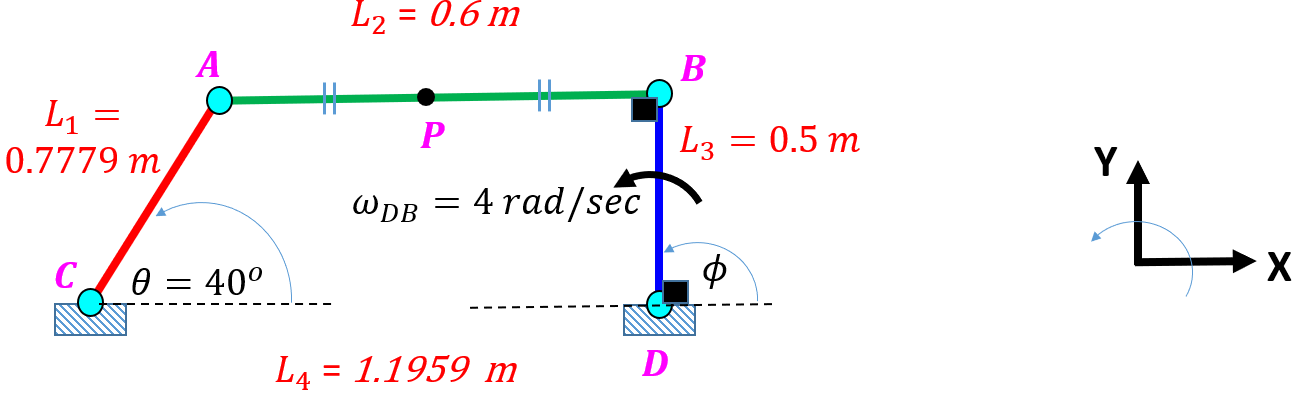

tf_open_model = true;                                        

#### The INITIAL joint angles:

theta_0_rad       = my_theta;
phi_0             = pi/2;

#### The known INITIAL joint velocity:

phi_dot_0_rad     = my_omega_DB;

#### Define parameters needed by Simscape model:

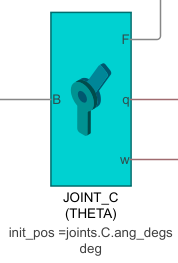  and 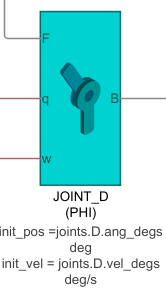

joints.C.ang_degs = rad2deg(theta_0_rad);
joints.D.ang_degs = rad2deg(phi_0);
joints.D.vel_degs = rad2deg(phi_dot_0_rad);

And some more parameters that the Simscape model needs:

density = 1000; % kg/m3
H       = my_L1/10;  % m
W       = my_L1/100; % m 
g       = 9.81;   % m/s^2

#### Open the model and explore:

if(true==tf_open_model)
    THE_MODEL = 'bh_4bar_model_simple_VEL_ANALYSIS';
    open_system(THE_MODEL);
end

#### Run the Simulink model:

You can run the Simulink model by pushing the Run button(shown below):

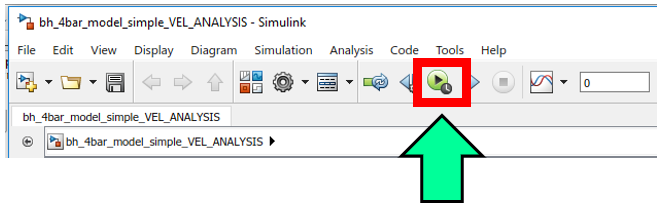

Note how the Simulink model confirms our previous computations:

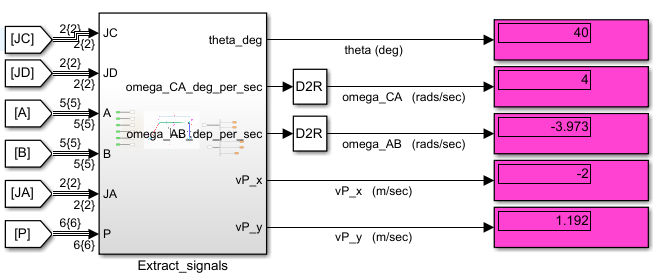     

# **Local functions only beyond this point**

**NOTE:**

- We'll use the REAL declaration for our SYMBOLIC symbols AND the standard MATLAB `cross` function

- The local code snippet commented out below is not needed

% function c = cross(a,b)
% 
%     c1 = a(2).*b(3)-a(3).*b(2);
%     c2 = a(3).*b(1)-a(1).*b(3);
%     c3 = a(1).*b(2)-a(2).*b(1);
% 
%     c  = [c1;c2;c3]; 
% 
% end